# Intro

imshow(imread(fullfile("Esempi","ex_box_3.jpg")));

# Dataset

clear; clc; close all



path = fullfile('Dataset','Da usare');

imgs = imageDatastore(path,"IncludeSubfolders",true,"LabelSource","foldernames");



%imgsSubset = subset(imgs, 1:2);
%figure;
%montage(imgsSubset);

# EDA

numero bn

Immagini_totali = numel(imgs.Labels)

Immagini_totali = 114548

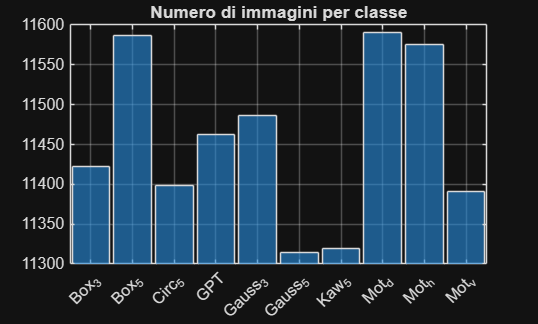


% 1. Crea una nuova figura
figure;

% 2. Genera l'istogramma partendo dalle etichette del datastore
histogram(imgs.Labels);

% 3. Aggiungi titoli e dettagli grafici per renderlo leggibile
title('Numero di immagini per classe');
ylim([11300, 11600]);

ax = gca;
ax.YAxis.Exponent = 0;
ytickformat('%.0f')

% 4. Opzionale: Ruota le etichette sull'asse X se i nomi delle classi sono lunghi
xtickangle(45);

% 5. Opzionale: Aggiungi una griglia di sfondo per leggere meglio i valori
grid on;

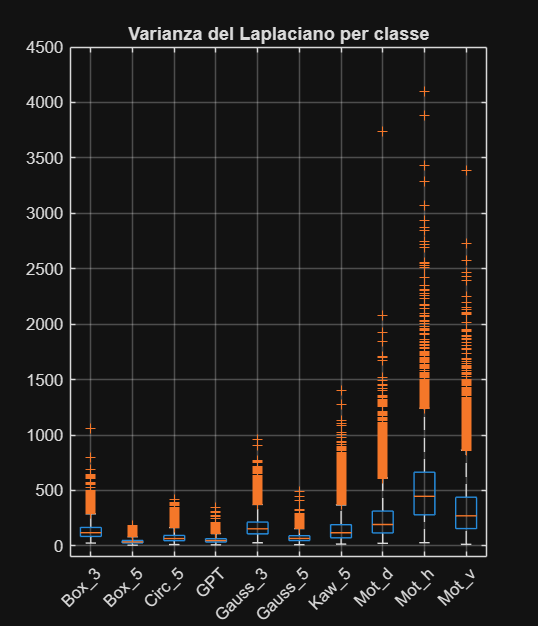



figure;

% 2. Correlation Plot: Alcohol vs Quality
%subplot(1, 2, 2);
T = readtable('laplacian_values.csv', ...
    'Delimiter', ',', ...
    'ReadVariableNames', true, ...
    'VariableNamingRule', 'preserve');

figure;
boxplot(T.LapVariance, T.Label);
ylim([-100, 4500]);
set(gcf, 'Position', [100, 100, 600, 700]);

title('Varianza del Laplaciano per classe');


xtickangle(45);
grid on;